format long

## Initial points and Polyline

% Waypoints
p1 = [0 -1 1];
p2 = [0 1 -2];
p3 = [2 1 0];

pts.x = [p1(1) p2(1) p3(1)];
pts.y = [p1(2) p2(2) p3(2)];
pts.z = [p1(3) p2(3) p3(3)];

figure
plot3Dpoints(pts, 'o')
hold on

p2p1 = p2-p1

p2p1 =      0     2    -3


norm_p2p1 = norm(p2p1)

norm_p2p1 =    3.605551275463989


p2p1_versor = p2p1 / norm_p2p1

p2p1_versor =                    0   0.554700196225229  -0.832050294337844



p3p2 = p3-p2

p3p2 =      2     0     2


norm_p3p2 = norm(p3p2)

norm_p3p2 =    2.828427124746190


p3p2_versor = p3p2 / norm_p3p2

p3p2_versor =    0.707106781186547                   0   0.707106781186547



% Polyline
N = 1000000;    % Number Of Segments

pts_p2p1.x = linspace(p1(1),p2(1),N);
pts_p2p1.y = linspace(p1(2),p2(2),N);
pts_p2p1.z = linspace(p1(3),p2(3),N);

plot3Dpoints(pts_p2p1, '.')

pts_p3p2.x = linspace(p2(1),p3(1),N);
pts_p3p2.y = linspace(p2(2),p3(2),N);
pts_p3p2.z = linspace(p2(3),p3(3),N);

plot3Dpoints(pts_p3p2, '.')

## Query points

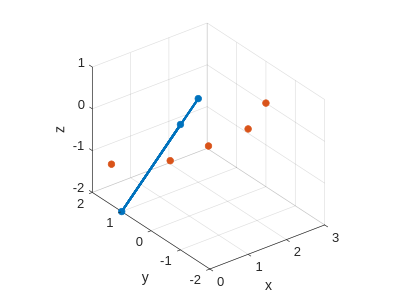

qp1 = [1 -2 1];
qp2 = [0.5 0 -0.5];
qp3 = [1.5 0 -0.5];
qp4 = [3 0 0];
qp5 = [0.5 2 -1.5];

qpts.x = [qp1(1) qp2(1) qp3(1) qp4(1) qp5(1)];
qpts.y = [qp1(2) qp2(2) qp3(2) qp4(2) qp5(2)];
qpts.z = [qp1(3) qp2(3) qp3(3) qp4(3) qp5(3)];

plot3Dpoints(qpts, 'o', [0.8500 0.3250 0.0980])

## QuadraticPolyline3Cost

kCostWeight = 5.0;

closest_to_qp1 = [0, -1, 1];
cost = kCostWeight * 0.5 * norm(qp1-closest_to_qp1)^2 % 1/2 * w * (qp1 - closest)^2

cost =    5.000000000000001



closest_to_qp2 = [0, 0, -0.5];
cost = kCostWeight * 0.5 * norm(qp2-closest_to_qp2)^2 % 1/2 * w * (qp2 - closest)^2

cost =    0.625000000000000
